clc; clear;
load("C:\Users\fabia\OneDrive\Desktop\Autonomus_Soaring\autonomous-soaring\Calculations\Sim_daten\2024-02-13 23-32-40.bin-294929.mat")


res = GPS_0(:,5)/1000

res = 1.0e+05 *

    2.5398
    2.5398
    2.5398
    2.5398
    2.5398
    2.5398
    2.5398
    2.5398
    2.5398
    2.5398


res = res/3600

res =    70.5495
   70.5496
   70.5496
   70.5497
   70.5497
   70.5498
   70.5498
   70.5499
   70.5499
   70.5500


res = mod(res,24)

res =    22.5495
   22.5496
   22.5496
   22.5497
   22.5497
   22.5498
   22.5498
   22.5499
   22.5499
   22.5500




% Initialize an array for the converted times
convertedTimes_Week = res

convertedTimes_Week =    22.5495
   22.5496
   22.5496
   22.5497
   22.5497
   22.5498
   22.5498
   22.5499
   22.5499
   22.5500



% Loop through each value and convert to hours.minutes format
for i = 1:length(res)
    % Extract the integer part (hours)
    hours = floor(res(i));

    % Extract the decimal part (fraction of an hour)
    fractionOfHour = res(i) - hours;

    % Convert the fraction of an hour to minutes and seconds
    minutes = floor(fractionOfHour * 60);
    seconds = (fractionOfHour * 60 - minutes) * 60;

    % Store the result in the new array
    convertedTimes_Week(i) = hours + minutes / 100 + seconds / 10000;
end
convertedTimes_Week = GPS_0(:,5)

convertedTimes_Week =    253978200
   253978400
   253978600
   253978800
   253979000
   253979200
   253979400
   253979600
   253979800
   253980000


convertedTimes = GPS_0(:,2)

convertedTimes =     23229387
    23429314
    23629397
    23829100
    24029192
    24229541
    24429303
    24629747
    24829417
    25029523


% Timestamp US
T = table(convertedTimes,convertedTimes_Week,GPS_0(:,11),GPS_0(:,9),GPS_0(:,10),GPS_0(:,12),GPS_0(:,13), 'VariableNames', {'Timestamp','Timestamp Daytime','ALT','Lat','Long','G-Speed [m/s]','GroundCourse'})

T = 1575×7 table
    Timestamp     Timestamp Daytime     ALT       Lat       Long     G-Speed [m/s]    GroundCourse
    __________    _________________    ______    ______    ______    _____________    ____________

    2.3229e+07       2.5398e+08        444.75    47.343    8.2572            0           87.398   
    2.3429e+07       2.5398e+08        444.75    47.343    8.2572        0.001           282.69   
    2.3629e+07       2.5398e+08        444.75    47.343    8.2572            0            83.26   
    2.3829e+07       2.5398e+08        444.75    47.343    8.2572        0.001           90.366   
    2.4029e+07       2.5398e+08        444.75    47.343    8.2572        0.001           100.36   
     2.423e+07       2.5398e+08        444.75    47

% Fixing Alt that it over ground
T.ALT = T.ALT - T.ALT(1);

GyroX =nan(1,length(GPS_0(:,2)));
GyroY =nan(1,length(GPS_0(:,2)));
GyroZ =nan(1,length(GPS_0(:,2)));
AcceX =nan(1,length(GPS_0(:,2)));
AcceY =nan(1,length(GPS_0(:,2)));
AcceZ =nan(1,length(GPS_0(:,2)));


for i = 1:length(GyroX)
    timestampTable = GPS_0(i,2);
    for j = 1:length(IMU_1(:,2))
        if timestampTable == IMU_1(j,2)
            GyroX(i) = IMU_1(j,4);
            GyroY(i) = IMU_1(j,5);
            GyroZ(i) = IMU_1(j,6);
            AcceX(i) = IMU_1(j,7);
            AcceY(i) = IMU_1(j,8);
            AcceZ(i) = IMU_1(j,9);
        end
    end
end
GyroX

GyroX =     0.0002    0.0000    0.0003    0.0003    0.0004    0.0003    0.0001    0.0006    0.0003    0.0004   -0.0095   -0.0287   -0.0389   -0.0028   -0.0512   -0.0135    0.0302    0.0492    0.0694    0.1147    0.2205    0.1626    0.0664    0.0521    0.0451    0.0085   -0.0020   -0.0011   -0.0008   -0.0005   -0.0007   -0.0007   -0.0007   -0.0003   -0.0000   -0.0014   -0.0446   -0.0991   -0.3043    0.0080    0.0058   -0.0005   -0.0004    0.0022    0.0023    0.0021    0.0015    0.0016    0.0019    0.0019


countNonNaN = sum(~isnan(GyroX));
countNonNaN

countNonNaN = 1575


T.GyroX = GyroX';
T.GyroY = GyroY';
T.GyroZ = GyroZ';
T.AcceX = AcceX';
T.AcceY = AcceY';
T.AcceZ = AcceZ'

T = 1575×13 table
    Timestamp     Timestamp Daytime     ALT      Lat       Long     G-Speed [m/s]    GroundCourse      GyroX         GyroY         GyroZ        AcceX     AcceY      AcceZ 
    __________    _________________    _____    ______    ______    _____________    ____________    __________    __________    __________    _______    ______    _______

    2.3229e+07       2.5398e+08            0    47.343    8.2572            0           87.398       0.00017241      0.001145    0.00038671    0.62521    1.4467    -9.7372
    2.3429e+07       2.

%Airspeed
% Initialize an array to store the indices
closestIndices = zeros(size(GPS_0, 1), 1);

% Loop over each timestamp in the first vector
for i = 1:size(GPS_0, 1)
    % Find the index in the second vector with the closest timestamp
    [~, index] = min(abs(ARSP_0(:,2) - GPS_0(i,2)));
    % Store the index in the array
    closestIndices(i) = index;
end

% Now, closestIndices contains the indices in the second vector corresponding to the closest timestamps in the first vector
closestIndices

closestIndices =      1
     3
     5
     7
     9
    11
    13
    15
    17
    19




Airspeed = ARSP_0(closestIndices,4)

Airspeed =     0.0221
    0.0221
    0.0221
    0.0221
    0.0221
    0.0221
    0.0221
    0.0221
    0.0221
    0.0221



T.Airspeed = Airspeed

T = 1575×14 table
    Timestamp     Timestamp Daytime     ALT      Lat       Long     G-Speed [m/s]    GroundCourse      GyroX         GyroY         GyroZ        AcceX     AcceY      AcceZ     Airspeed
    __________    _________________    _____    ______    ______    _____________    ____________    __________    __________    __________    _______    ______    _______    ________

    2.3229e+07       2.5398e+08            0    47.343    8.2572            0           87.398       0.00017241      0.001145    0.000386

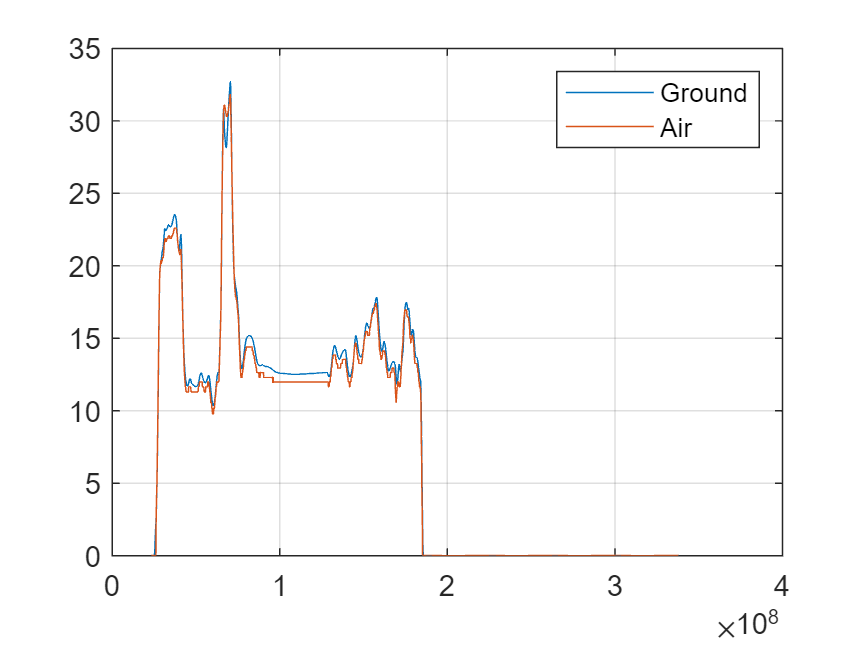



plot(T.Timestamp,T.("G-Speed [m/s]"),T.Timestamp,T.Airspeed)
hold on
grid on
legend('Ground','Air')
hold off

%Baro and Temp
% Initialize an array to store the indices
closestIndices = zeros(size(GPS_0, 1), 1);

% Loop over each timestamp in the first vector
for i = 1:size(GPS_0, 1)
    % Find the index in the second vector with the closest timestamp
    [~, index] = min(abs(BARO_0(:,2) - GPS_0(i,2)));
    % Store the index in the array
    closestIndices(i) = index;
end

% Now, closestIndices contains the indices in the second vector corresponding to the closest timestamps in the first vector
closestIndices

closestIndices =      1
     3
     5
     7
     9
    11
    13
    15
    17
    19




Barometer = BARO_0(closestIndices,5)

Barometer = 1.0e+04 *

    9.6097
    9.6095
    9.6096
    9.6096
    9.6093
    9.6094
    9.6097
    9.6097
    9.6096
    9.6096


T.Barometer = Barometer

T = 1575×15 table
    Timestamp     Timestamp Daytime     ALT      Lat       Long     G-Speed [m/s]    GroundCourse      GyroX         GyroY         GyroZ        AcceX     AcceY      AcceZ     Airspeed    Barometer
    __________    _________________    _____    ______    ______    _____________    ____________    __________    __________    __________    _______    ______    _______    ________    _________

    2.3229e+07       2.5398e+08            0    47.343    8.2572            0

Temperature = BARO_0(closestIndices,6)

Temperature =    28.8300
   28.8500
   28.8700
   28.8900
   28.9100
   28.9400
   28.9600
   28.9800
   29.0000
   29.0200


T.Temperature = Temperature

T = 1575×16 table
    Timestamp     Timestamp Daytime     ALT      Lat       Long     G-Speed [m/s]    GroundCourse      GyroX         GyroY         GyroZ        AcceX     AcceY      AcceZ     Airspeed    Barometer    Temperature
    __________    _________________    _____    ______    ______    _____________    ____________    __________    __________    __________    _______    ______    _______    ________    _________    ___________

    2.3229e+0

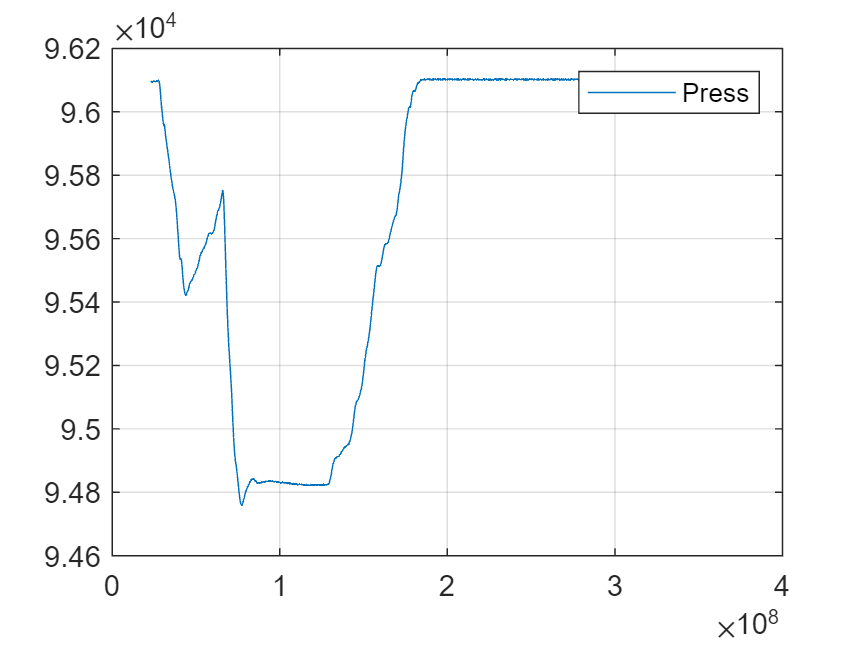


plot(T.Timestamp,T.Barometer)
hold on
grid on
legend('Press')
hold off

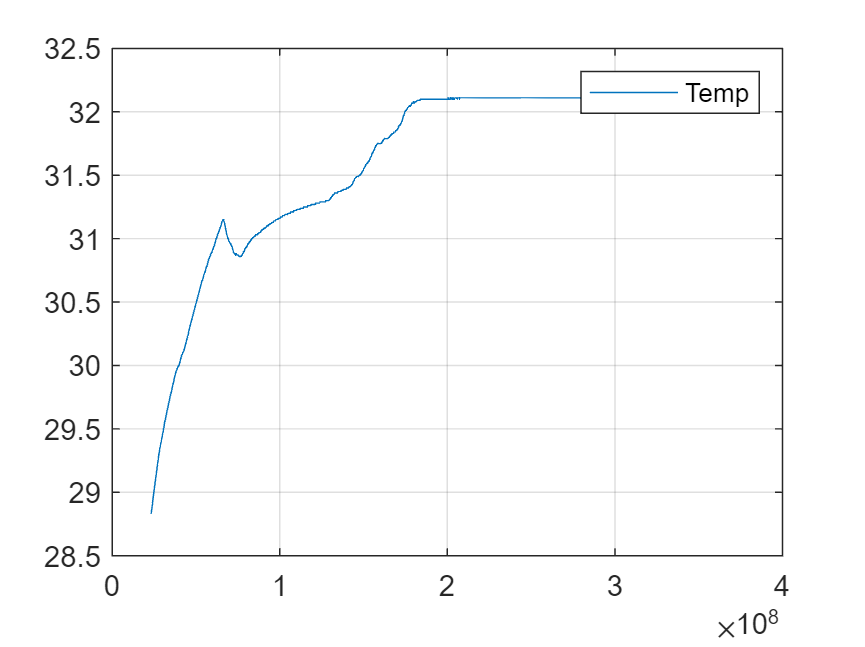


plot(T.Timestamp,T.Temperature)
hold on
grid on
legend('Temp')
hold off

% Energie
Energie =nan(1,length(GPS_0(:,2)));
g= 9.81

g = 9.8100


for i = 1:size(GPS_0, 1)
    Energie(i) = 1./(2*g)*(T.Airspeed(i))^2+T.ALT(i);
end

Energie

Energie =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0300    0.3468    0.7235    1.0902    1.8637    3.0339    4.6109    6.9913    9.4218   12.7657   15.4062   18.6333   20.4936   22.2071   23.7538   25.4205   26.2138   27.3138   28.6305   29.4205   30.6173   31.4573   32.2773   33.2940   34.4775   35.5210   36.1877   37.0645   37.8045   38.3977   39.2477   39.8777   40.5477   41.6245   42.3045   42.9345



% Ableitung
EnergieAb =nan(1,length(GPS_0(:,2)));
for i = 2:(length(Energie))
    EnergieAb(i) = Energie(i)-Energie(i-1);
end

EnergieAb

EnergieAb =        NaN         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.0300    0.3767    0.3767    0.3667    0.7735    1.1702    1.5770    2.3804    2.4304    3.3439    2.6405    3.2272    1.8602    1.7135    1.5467    1.6668    0.7932    1.1000    1.3168    0.7900    1.1967    0.8400    0.8200    1.0167    1.1835    1.0435    0.6668    0.8767    0.7400    0.5933    0.8500    0.6300    0.6700    1.0767    0.6800    0.6300



T.Energie = Energie';
T.EnergieAbleitung = EnergieAb'

T = 1575×18 table
    Timestamp     Timestamp Daytime     ALT      Lat       Long     G-Speed [m/s]    GroundCourse      GyroX         GyroY         GyroZ        AcceX     AcceY      AcceZ     Airspeed    Barometer    Temperature     Energie      EnergieAbleitung
    __________    _________________    _____    ______    ______    _____________    ____________    __________    __________    __________    _______    ______    _______    ________    

%Heading Roll Pitch Yaw
% Initialize an array to store the indices
closestIndices = zeros(size(GPS_0, 1), 1);

% Loop over each timestamp in the first vector
for i = 1:size(GPS_0, 1)
    % Find the index in the second vector with the closest timestamp
    [~, index] = min(abs(ATT(:,2) - GPS_0(i,2)));
    % Store the index in the array
    closestIndices(i) = index;
end

% Now, closestIndices contains the indices in the second vector corresponding to the closest timestamps in the first vector
closestIndices

closestIndices =      3
     8
    13
    18
    23
    28
    33
    38
    43
    48



% Convert into RADIANS and save in Table
ROLL = ATT(closestIndices,4)

ROLL =    -8.4900
   -8.4900
   -8.4900
   -8.4900
   -8.4900
   -8.4900
   -8.4900
   -8.4900
   -8.4900
   -8.4900


ROLL = (ROLL)

ROLL =    -8.4900
   -8.4900
   -8.4900
   -8.4900
   -8.4900
   -8.4900
   -8.4900
   -8.4900
   -8.4900
   -8.4900


T.Roll = ROLL

T = 1575×19 table
    Timestamp     Timestamp Daytime     ALT      Lat       Long     G-Speed [m/s]    GroundCourse      GyroX         GyroY         GyroZ        AcceX     AcceY      AcceZ     Airspeed    Barometer    Temperature     Energie      EnergieAbleitung     Roll 
    __________    _________________    _____    ______    ______    _____________    ____________    __________    __________    __________    _______    ______    _______    


PITCH = ATT(closestIndices,6)

PITCH =     3.8900
    3.8900
    3.8900
    3.8900
    3.8900
    3.8900
    3.8900
    3.8900
    3.8900
    3.8900


PITCH = (PITCH)

PITCH =     3.8900
    3.8900
    3.8900
    3.8900
    3.8900
    3.8900
    3.8900
    3.8900
    3.8900
    3.8900


T.Pitch = PITCH

T = 1575×20 table
    Timestamp     Timestamp Daytime     ALT      Lat       Long     G-Speed [m/s]    GroundCourse      GyroX         GyroY         GyroZ        AcceX     AcceY      AcceZ     Airspeed    Barometer    Temperature     Energie      EnergieAbleitung     Roll     Pitch 
    __________    _________________    _____    ______    ______    _____________    ____________    __________    __________    __________    _______    ______    


YAW = ATT(closestIndices,8)

YAW =    91.3900
   91.3900
   91.3900
   91.3900
   91.3900
   91.3900
   91.3900
   91.3900
   91.4000
   91.4000


YAW = (YAW)

YAW =    91.3900
   91.3900
   91.3900
   91.3900
   91.3900
   91.3900
   91.3900
   91.3900
   91.4000
   91.4000


T.Yaw = YAW

T = 1575×21 table
    Timestamp     Timestamp Daytime     ALT      Lat       Long     G-Speed [m/s]    GroundCourse      GyroX         GyroY         GyroZ        AcceX     AcceY      AcceZ     Airspeed    Barometer    Temperature     Energie      EnergieAbleitung     Roll     Pitch      Yaw 
    __________    _________________    _____    ______    ______    _____________    ____________    __________    __________    __________    _______    _

%Humidity
T.Humidity = repmat(20, height(T), 1)

T = 1575×22 table
    Timestamp     Timestamp Daytime     ALT      Lat       Long     G-Speed [m/s]    GroundCourse      GyroX         GyroY         GyroZ        AcceX     AcceY      AcceZ     Airspeed    Barometer    Temperature     Energie      EnergieAbleitung     Roll     Pitch      Yaw     Humidity
    __________    _________________    _____    ______    ______    _____________    ____________    __________    __________    __________    

FontSize = 30;
LineWidth = 100;
gx = geoscatter(T.Lat(2:end),T.Long(2:end),LineWidth)

gx =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
          LineWidth: 0.5000
       LatitudeData: [47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 47.3425 … ]
      LongitudeData: [8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2572 8.2573 8.2573 8.2573 8.2573 8.2573 8.2574 8.2574 8.2575 8.2575 8.2576 8.2576 8.2577 8.2577 8.2578 8.2578 8.2579 … ]
              ZData: [1×0 double]
           SizeData: 100
              CData: [0 0.4470 0.7410]

  Show 

hold on;
lgd=legend("Flightpath",'Location','northwest')

lgd =   Legend (Flightpath) with properties:

         String: {'Flightpath'}
       Location: 'northwest'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.1798 0.8567 0.1839 0.0429]
          Units: 'normalized'

  Show all properties


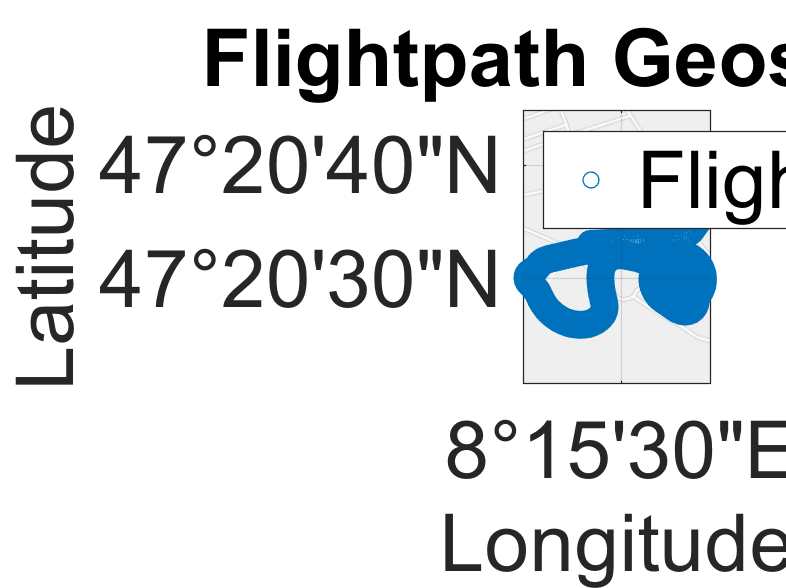

title("Flightpath Geoscatter")
fontsize(lgd,FontSize,'points');
fontsize(gca, FontSize,'points');
hold off;

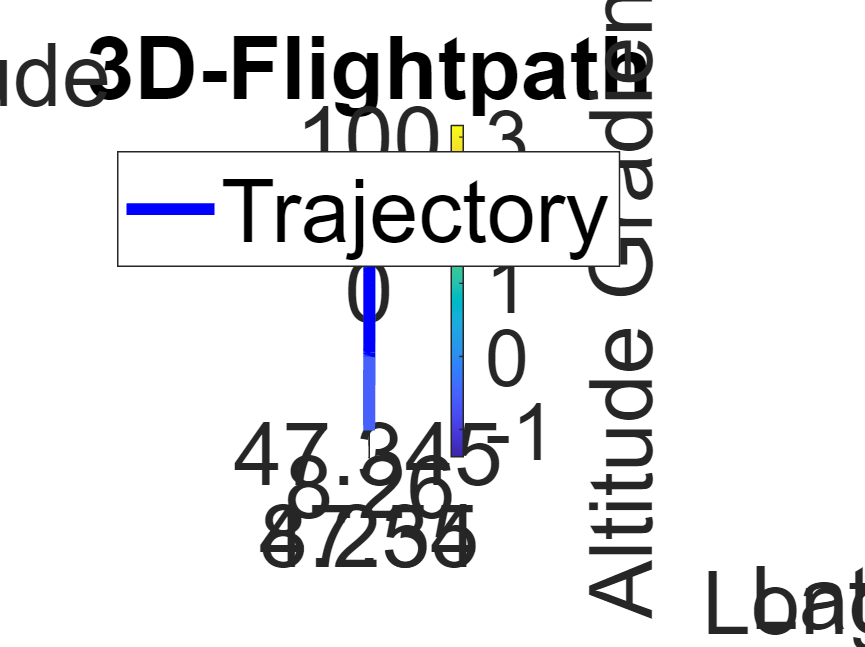

LineWidth = 4;
FontSize = 30;
% Plot the 3D trajectory
plot3(T.Long(2:end), T.Lat(2:end), T.ALT(2:end), 'b-', 'LineWidth', LineWidth);
hold on;

% Initialize gradient vector
gradient = zeros(size(T.ALT));

% Calculate gradient for each data point
for i = 2:length(T.ALT)
    altdiff = T.ALT(i) - T.ALT(i-1);
    gradient(i) = altdiff;
end

% Map gradient to colors
cd = colormap('parula');
cd = interp1(linspace(min(gradient), max(gradient), length(cd)), cd, gradient);
cd = uint8(cd' * 255);
cd(4, :) = 255;

% Plot lines from ground to each data point with different colors based on gradient
for i = 2:length(T.Long)
    % Select color for this line
    color = cd(:, i);
    
    % Plot the line with the determined color
    plot3([T.Long(i) T.Long(i)], [T.Lat(i) T.Lat(i)], [0 T.ALT(i)], 'Color', color, 'LineWidth', LineWidth);
end

% Create a colorbar
c = colorbar;
c.Label.String = 'Altitude Gradient';
caxis([min(gradient), max(gradient)]);
title("3D-Flightpath")
xlabel('Longitude');
ylabel("Latitude");
zlabel("Altitude");
% Create legend
lgd=legend('Trajectory', 'Location', 'Best');
fontsize(lgd,FontSize,'points');
fontsize(gca, FontSize,'points');

hold off;

% Create SAVE Tasble with correct data sequence
SaveTable = table(T.Timestamp,T.("Timestamp Daytime"),T.Humidity,T.("G-Speed [m/s]"),T.Airspeed,T.Temperature,T.Barometer,T.Long,T.Lat,T.ALT,T.Roll,T.Pitch,T.Yaw,T.GroundCourse,T.Energie,T.EnergieAbleitung,T.GyroX,T.GyroY,T.GyroZ,T.AcceX,T.AcceY,T.AcceZ,'VariableNames', {'Time since System Start [us]','Time Day','Humidity [%]','Groundspeed [m/s]','Airspeed [m/s]','Temperature [deg C]','Airpressure [kPas]','Longitude','Latitude','Flight Height [m]','Roll [deg]','Pitch [deg]','Yaw [deg]','Ground course','Energie [m]','Energieableitung [m/s]','GyroX','GyroY','GyroZ','AcceX','AcceY','AcceZ'})

SaveTable = 1575×22 table
    Time since System Start [us]     Time Day     Humidity [%]    Groundspeed [m/s]    Airspeed [m/s]    Temperature [deg C]    Airpressure [kPas]    Longitude    Latitude    Flight Height [m]    Roll [deg]    Pitch [deg]    Yaw [deg]    Ground course    Energie [m]    Energieableitung [m/s]      GyroX         GyroY         GyroZ        AcceX     AcceY      AcceZ 
    ____________________________    __________    ____________    _________________    ______________    ___________________    

writetable(SaveTable,'ShortFlight.csv','Delimiter',';')    

timediff(1) =0 ;
for i= 2:length(T.Timestamp)

   timediff(i-1) = T.Timestamp(i)-T.Timestamp(i-1);


end

i = 1:length(timediff)

i =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


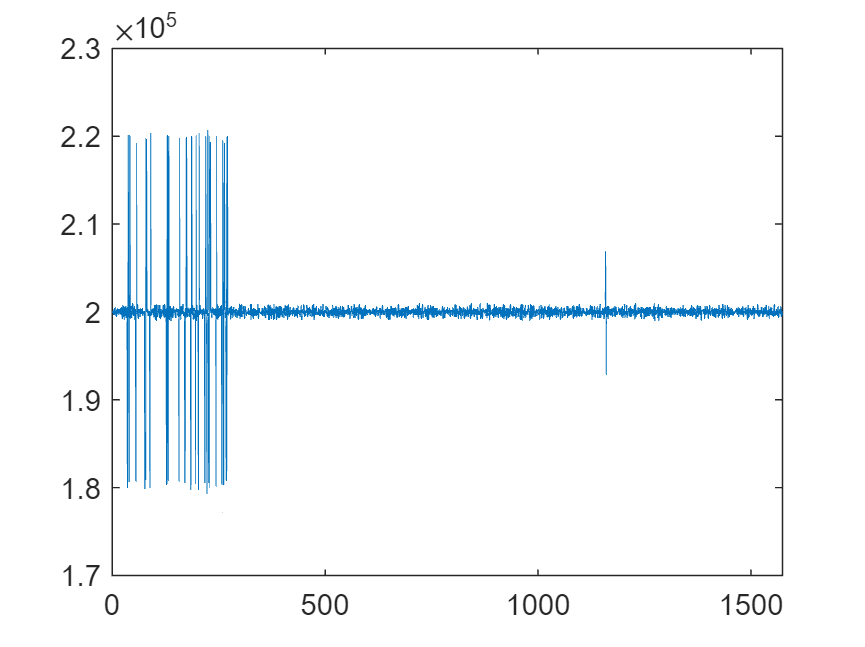

plot(i,timediff)

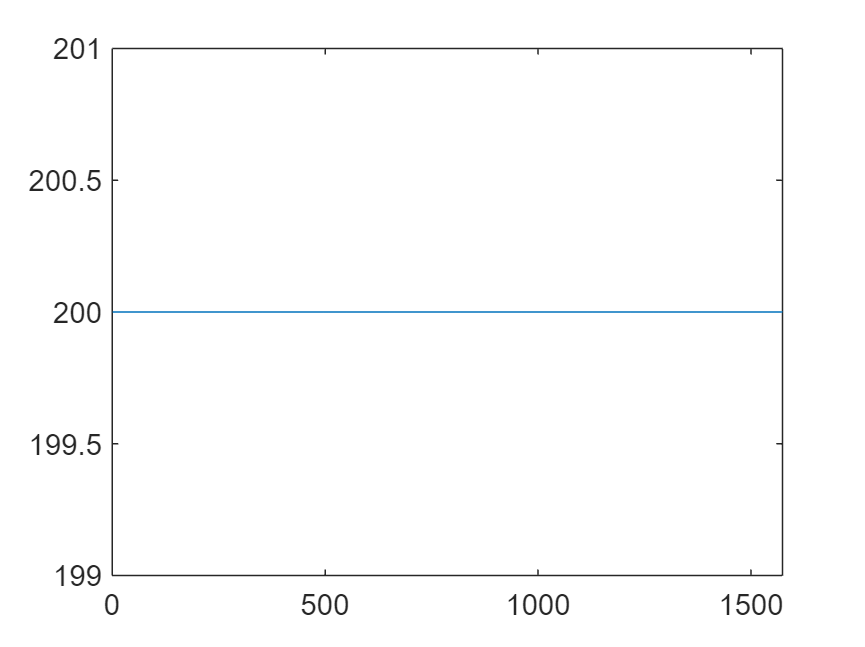


timediff(1) =0 ;
for i= 2:length(T.("Timestamp Daytime"))

   timediffDay(i-1) = T.("Timestamp Daytime")(i)-T.("Timestamp Daytime")(i-1);


end

i = 1:length(timediffDay);
plot(i,timediffDay)

index = 1;
for i=1:length(T.Timestamp)

    if T.Airspeed(i) > 1
        validYaw(index) = T.Yaw(i);
        validCourse(index) = T.GroundCourse(i);
        validAirspeed(index) = T.Airspeed(i);
        validGroundspeed(index) = T.("G-Speed [m/s]")(i);
        index = index + 1;
    end

end

headingdiff = abs(validCourse-validYaw);


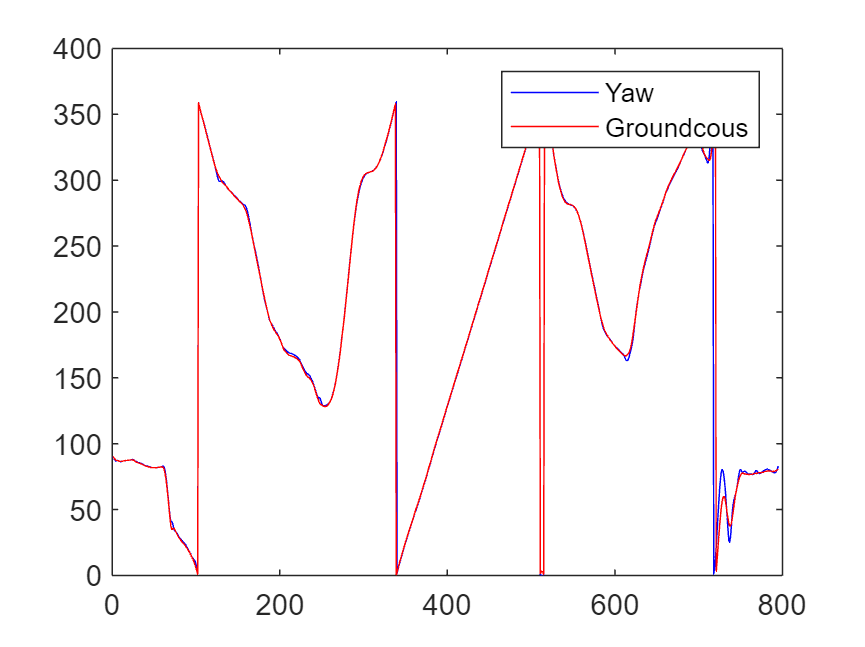

TF = isoutlier(headingdiff,"percentiles",[0 98]);

i = 1:length(validYaw);
plot(i,validYaw,'b')
hold on
plot (i,validCourse,'r')
legend('Yaw','Groundcous')
hold off;

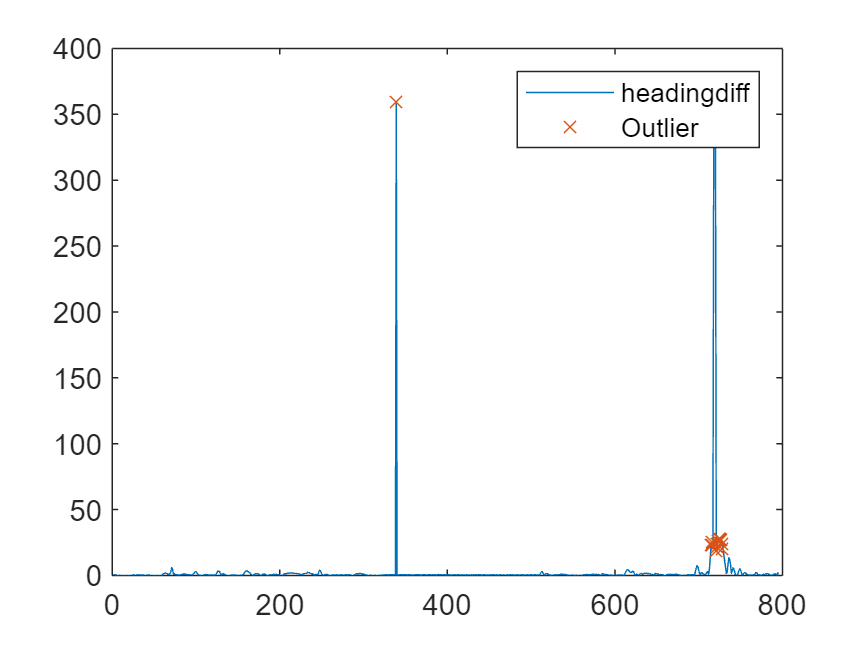


i = 1:length(headingdiff);
plot(i,headingdiff)
hold on;
plot(i(TF),headingdiff(TF),"x")
legend('headingdiff','Outlier')
hold off;

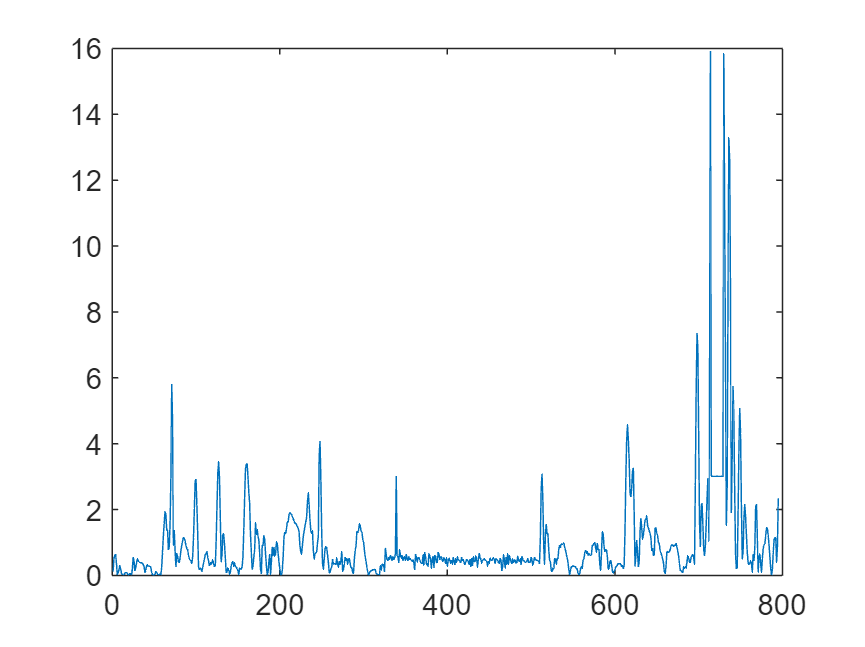

head_mean = mean(headingdiff);
headingdiff(TF) = head_mean;
i = 1:length(headingdiff);
plot(i,headingdiff)

i=sqrt(-1)

i = 0.0000 + 1.0000i

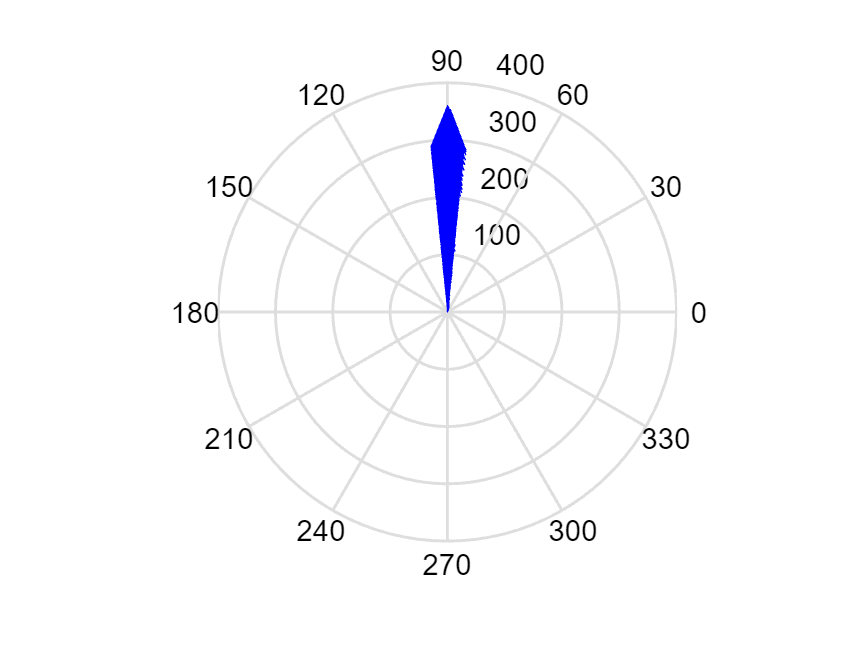




for j=1:length(validYaw)
    V_PAir(j) = validAirspeed(j)*exp(i*(deg2rad(validYaw(j))));
    V_PGround(j) = validGroundspeed(j)*exp(i*(deg2rad(validCourse(j))));
    V_PWind(j) = V_PGround(j)-V_PAir(j);
    Wind_angle(j) = rad2deg(angle(V_PWind(j)));
    if Wind_angle(j) < 0
        Wind_angle(j)= 360-abs(Wind_angle(j));
        Wind_ampl(j) = abs(V_PWind(j));
    else
        Wind_angle(j);
        Wind_ampl(j) = abs(V_PWind(j));
    end
end


h1 = compass(Wind_ampl, Wind_angle, 'b');